# Advent Of Code

## Day 3: Crossed Wires

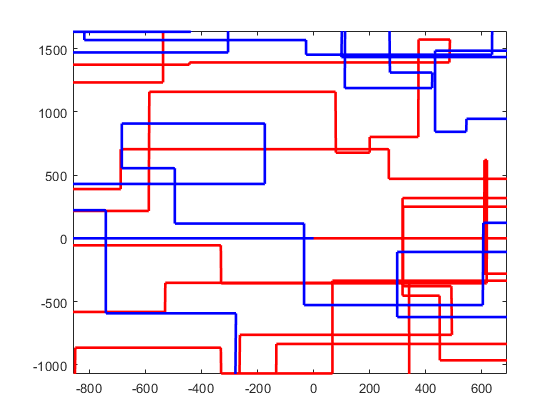

Wire1 = "R1009,D335,L942,D733,L398,U204,L521,D347,L720,U586,R708,D746,L292,U416,L824,U20,R359,D828,R716,U895,L498,D671,L325,D68,L667,U134,L435,D44,R801,U654,R188,U542,L785,D318,L806,U602,L465,U239,R21,U571,R653,U436,L52,U380,R446,D960,R598,U590,L47,U972,L565,D281,R790,U493,R864,D396,R652,D775,L939,D284,R554,U629,L842,D837,R554,D795,R880,D301,R948,U974,L10,D898,R588,D743,L334,U59,L413,U511,L132,U771,R628,D805,R465,D561,R18,D169,L580,D99,L508,U964,L870,D230,L472,U897,L85,U306,L103,U322,L637,U464,R129,D514,R454,U479,R801,U18,R929,U181,L113,D770,L173,D124,L122,U481,L666,D942,L534,U608,R90,U576,L641,U249,L857,U197,R783,D92,L938,D192,L698,D862,R995,U12,R766,D323,R934,U315,R956,D234,R983,D246,L153,U26,L779,D628,R174,D385,L758,D486,R132,U414,R915,D511,L152,D309,L708,D755,L679,D166,L699,U734,R55,D224,L582,U798,L348,U219,L304,U621,L788,D538,R781,D509,R486,U581,R759,D892,R16,D552,L82,D618,L309,D610,L645,U146,L328,U569,L307,D385,L249,D231,R928,U681,R384,D337,R715,D798,L788,D604,R517,U766,R368,U430,L49,U236,R621,U656,R997,U268,L18,D789,L935,D87,L670,U35,R463,D71,R268,U728,R693,D863,R656,D654,L350,U796,L72,U562,R56,U10,L651,D751,L557,D518,R901,D741,R787,D332,R723,D980,R206,U670,R645,D927,L641,D863,R478,D568,L858,D990,L124,D864,L162,U361,L407,U674,R508,D284,L675,D794,L138,U55,L781,U37,R956,D364,L111,U721,L91,U559,L852,U351,R994,U446,L162,D345,R92,D941,R572,U185,R615,D590,R459,D313,R127,D315,R96,U751,R210,D620,L790,U826,R410,D652,R549,D698,L805,U814,L364,U905,L96,U997,L689";
Wire2 = "L1008,D451,L146,D628,R877,U486,L464,U815,L119,U208,R686,U477,L510,D353,R189,D437,R461,D645,R639,U650,R491,D744,L798,U514,R598,U64,R668,U771,R21,U782,L564,U632,R23,U112,R947,U649,L205,D804,R277,U683,L828,U662,R890,U420,L908,U484,R535,D515,R390,U7,L287,D967,R497,U502,L893,D851,R426,D656,R622,U46,L106,U590,R646,D29,R467,D896,L155,U382,L992,D189,L34,U16,R132,U35,L586,U812,L539,D409,R776,D42,R58,U323,R569,D965,R648,D789,R478,D587,R162,D834,R979,D993,L944,U84,R93,U903,R491,U713,L646,U235,R120,U286,L919,U34,L662,U834,L812,D271,L73,U410,L758,U210,R712,U581,L520,D654,L981,D516,R312,U123,L153,U433,R368,U606,L882,U362,L261,U587,R441,D691,L699,U135,L825,D25,R142,U191,L358,D554,L487,D802,L542,D266,R283,U222,R113,D259,R828,U182,R402,U627,R769,D426,L768,U571,R118,U684,R803,D430,R942,U514,R711,D225,R299,U45,L214,U712,L673,U787,L164,D703,L616,D587,R624,D326,L614,D779,L904,D563,L98,U137,R687,U425,R615,U671,L361,D47,L767,D951,R791,D116,R664,U704,R291,U535,L322,D989,R467,U7,L974,D276,R901,U51,L567,D641,R112,U102,R753,D127,R486,D143,R259,U212,L97,U505,R377,U473,R514,D912,L928,U401,R772,D416,R695,U784,L524,D341,R402,U749,L1,U1,L109,U921,L754,U66,L927,U708,R551,D687,R129,D346,L408,D330,L300,D920,R170,D353,R97,D74,R850,D511,R275,U872,L748,U344,R610,D391,R963,D98,L89,U259,R651,U651,L31,D142,L104,U770,L482,D677,R823,D110,L606,U897,L631,U437,L551,D550,R301,D762,R349,D824,R260,U438,R249,D636,L386,U926,R367,U231,R752,U854,L481,D764,R516,D273,L726,D778,R483,U513,R129,D135,L224";
Wire1 = split(Wire1,","); Wire1 = transpose(Wire1);
Wire2 = split(Wire2,","); Wire2 = transpose(Wire2);


if numel(Wire1) > numel(Wire2)
    Wire2(numel(Wire2)+1: numel(Wire1)) = "D00";
elseif numel(Wire2) > numel(Wire1)
    Wire1(numel(Wire1)+1: numel(Wire2)) = "D00";
end
r1 = 1;
u1 = 1;
l1 = 1;
d1 = 1;
r2 = 1;
u2 = 1;
l2 = 1;
d2 = 1;
R1 = startsWith(Wire1, "R");
U1 = startsWith(Wire1, "U");
L1 = startsWith(Wire1, "L");
D1 = startsWith(Wire1, "D");
R2 = startsWith(Wire2, "R");
U2 = startsWith(Wire2, "U");
L2 = startsWith(Wire2, "L");
D2 = startsWith(Wire2, "D");
x1 = 0;
y1 = 0;
x2 = 0;
y2 = 0;
w1 = 1;
w2 = 1;
begin1 = [0 ; 0];
begin2 = [0 ; 0];
Weg1 = 0;
Weg2 = 0;
c = 1;
Coordinaten = 0;



R11 = Wire1(startsWith(Wire1, "R"));
U11 = Wire1(startsWith(Wire1, "U"));
L11 = Wire1(startsWith(Wire1, "L"));
D11 = Wire1(startsWith(Wire1, "D"));
R22 = Wire2(startsWith(Wire2, "R"));
U22 = Wire2(startsWith(Wire2, "U"));
L22 = Wire2(startsWith(Wire2, "L"));
D22 = Wire2(startsWith(Wire2, "D"));

if numel(R11) < numel(R22)
    R11([numel(R11)+1: numel(R22)]) = "00";
elseif numel(R11) > numel(R22)
    R22([numel(R22)+1: numel(R11)]) = "00";
end

if numel(U11) < numel(U22)
    U11([numel(U11)+1: numel(U22)]) = "00";
elseif numel(U11) > numel(U22)
    U22([numel(U22)+1: numel(U11)]) = "00";
end

if numel(L11) < numel(L22)
    L11([numel(L11)+1: numel(L22)]) = "00";
elseif numel(L11) > numel(L22)
    L22([numel(L22)+1: numel(L11)]) = "00";
end

if numel(D11) < numel(D22)
    D11([numel(D11)+1: numel(D22)]) = "00";
elseif numel(D11) > numel(D22)
    D22([numel(D22)+1: numel(D11)]) = "00";
end

RR = [R11 ; R22];
UU = [U11 ; U22];
LL = [L11 ; L22];
DD = [D11 ; D22];

RR = char(RR);
RR = RR(:,2:end,:);
UU = char(UU);
UU = UU(:,2:end,:);
LL = char(LL);
LL = LL(:,2:end,:);
DD = char(DD);
DD = DD(:,2:end,:);

for i=1:numel(Wire1)
    if R1(i)==1
        x1 = x1 + str2double(RR(1,:,r1));
        r1 = r1 + 1;
        weg1(1,w1) = x1;
        w1 = w1 + 1;
        
    elseif U1(i)==1
        y1 = y1 + str2double(UU(1,:,u1));
        u1 = u1 + 1;
        weg1(2,w1) = y1;
        w1 = w1 + 1;
    elseif L1(i)==1
        x1 = x1 - str2double(LL(1,:,l1));
        l1 = l1 + 1;
        weg1(1,w1) = x1;
        w1 = w1 + 1;
    elseif D1(i)==1
        y1 = y1 - str2double(DD(1,:,d1));
        d1 = d1 + 1;
        weg1(2,w1) = y1;
        w1 = w1 + 1;
    end
    
    
    if R2(i)==1
        x2 = x2 + str2double(RR(2,:,r2));
        r2 = r2 + 1;
        weg2(1,w2) = x2;
        w2 = w2 + 1;
    elseif U2(i)==1
        y2 = y2 + str2double(UU(2,:,u2));
        u2 = u2 + 1;
        weg2(2,w2) = y2;
        w2 = w2 + 1;
    elseif L2(i)==1
        x2 = x2 - str2double(LL(2,:,l2));
        l2 = l2 + 1;
        weg2(1,w2) = x2;
        w2 = w2 + 1;
    elseif D2(i)==1
        y2 = y2 - str2double(DD(2,:,d2));
        d2 = d2 + 1;
        weg2(2,w2) = y2;
        w2 = w2 + 1;
    end
end


if weg1(1,1)~=0 % Weg 1
    Rij = 1;
else
    Rij = 2;
end

if Rij == 1
    notRij = 2;
else
    notRij = 1;
end

r = 1;

if begin1(Rij) < weg1(Rij,r)
    Weg1(Rij,r:weg1(Rij,r)+1) = begin1(Rij):weg1(Rij,r); %% 1ste keer x
    Weg1(notRij,r:weg1(Rij,r)+1) = weg1(notRij,r);
elseif weg1(Rij,r) < begin1(Rij)
    Weg1(Rij,r:weg1(Rij,r)+1) = begin1(Rij):-1:weg1(Rij,r); %% 1ste keer x
    Weg1(notRij,r:weg1(Rij,r)+1) = weg1(notRij,r);
end

begin1(Rij) = weg1(Rij,r);
hulp = Rij;
r = r+1;
Rij = notRij;
notRij = hulp;

if begin1(Rij) < weg1(Rij,r)
    Weg1(Rij,weg1(notRij,r-1)+1:(weg1(notRij,r-1))+abs(weg1(Rij,r))+1) = begin1(Rij):weg1(Rij,r); %% 1ste keer y
    Weg1(notRij,weg1(notRij,r-1)+1:(weg1(notRij,r-1))+abs(weg1(Rij,r))+1) = weg1(notRij,r-1);
elseif weg1(Rij,r) < begin1(Rij)
    Weg1(Rij,weg1(notRij,r-1)+1:(weg1(notRij,r-1))+abs(weg1(Rij,r))+1) = begin1(Rij):-1:weg1(Rij,r); %% 1ste keer y
    Weg1(notRij,weg1(notRij,r-1)+1:(weg1(notRij,r-1))+abs(weg1(Rij,r))+1) = weg1(notRij,r-1);
end

begin1(Rij) = weg1(Rij,r);
hulp = Rij;
Rij = notRij;
notRij = hulp;

for r = 3:length(weg1)
    if begin1(Rij) < weg1(Rij,r)
        Lengte = length(Weg1);
        Weg1(Rij,Lengte:Lengte+abs((weg1(Rij,r))-weg1(Rij,r-2))) = begin1(Rij):weg1(Rij,r);
        Weg1(notRij,Lengte:Lengte+abs((weg1(Rij,r))-weg1(Rij,r-2))) = weg1(notRij,r-1);
    elseif weg1(Rij,r) < begin1(Rij)
        Lengte = length(Weg1);
        Weg1(Rij,Lengte:Lengte+abs((weg1(Rij,r))-weg1(Rij,r-2))) = begin1(Rij):-1:weg1(Rij,r);
        Weg1(notRij,Lengte:Lengte+abs((weg1(Rij,r))-weg1(Rij,r-2))) = weg1(notRij,r-1);
    end
    
    begin1(Rij) = weg1(Rij,r);
    hulp = Rij;
    Rij = notRij;
    notRij = hulp;
    
end

if weg2(1,1)~=0 % Weg 2
    Rij = 1;
else
    Rij = 2;
end

if Rij == 1
    notRij = 2;
else
    notRij = 1;
end

r = 1;

if begin2(Rij) < weg2(Rij,r)
    Weg2(Rij,r:abs(weg2(Rij,r))+1) = begin2(Rij):weg2(Rij,r); %% 1ste keer x
    Weg2(notRij,r:weg2(Rij,r)+1) = weg2(notRij,r);
elseif weg2(Rij,r) < begin2(Rij)
    Weg2(Rij,r:abs(weg2(Rij,r))+1) = begin2(Rij):-1:weg2(Rij,r); %% 1ste keer x
    Weg2(notRij,r:weg2(Rij,r)+1) = weg2(notRij,r);
end

begin2(Rij) = weg2(Rij,r);
hulp = Rij;
r = r+1;
Rij = notRij;
notRij = hulp;

if begin2(Rij) < weg2(Rij,r)
    Weg2(Rij,abs(weg2(notRij,r-1))+1:(weg2(notRij,r-1))+abs(weg2(Rij,r))+1) = begin2(Rij):weg2(Rij,r); %% 1ste keer y
    Weg2(notRij,weg2(notRij,r-1)+1:(weg2(notRij,r-1))+abs(weg2(Rij,r))+1) = weg2(notRij,r-1);
elseif weg2(Rij,r) < begin2(Rij)
    Weg2(Rij,abs(weg2(notRij,r-1))+1:(abs(weg2(notRij,r-1)))+abs(weg2(Rij,r))+1) = begin2(Rij):-1:weg2(Rij,r); %% 1ste keer y
    Weg2(notRij,abs(weg2(notRij,r-1)+1):(abs(weg2(notRij,r-1)))+abs(weg2(Rij,r))+1) = weg2(notRij,r-1);
end

begin2(Rij) = weg2(Rij,r);
hulp = Rij;
Rij = notRij;
notRij = hulp;

for r = 3:length(weg2)
    if begin2(Rij) < weg2(Rij,r)
        Lengte = length(Weg2);
        Weg2(Rij,Lengte:Lengte+abs((weg2(Rij,r))-weg2(Rij,r-2))) = begin2(Rij):weg2(Rij,r);
        Weg2(notRij,Lengte:Lengte+abs((weg2(Rij,r))-weg2(Rij,r-2))) = weg2(notRij,r-1);
    elseif weg2(Rij,r) < begin2(Rij)
        Lengte = length(Weg2);
        Weg2(Rij,Lengte:Lengte+abs((weg2(Rij,r))-weg2(Rij,r-2))) = begin2(Rij):-1:weg2(Rij,r);
        Weg2(notRij,Lengte:Lengte+abs((weg2(Rij,r))-weg2(Rij,r-2))) = weg2(notRij,r-1);
    end
    
    begin2(Rij) = weg2(Rij,r);
    hulp = Rij;
    Rij = notRij;
    notRij = hulp;
    
end

% Wegen tekenen en vergelijken


plot(Weg1(1,:),Weg1(2,:),'Color','r','LineWidth',2)
hold on
plot(Weg2(1,:),Weg2(2,:),'Color','b','LineWidth',2)


if length(Weg1) > length(Weg2)
    Weg2(1:2,length(Weg2)+1:length(Weg1))=nan;
elseif length(Weg1) < length(Weg2)
    Weg1(1:2,length(Weg1)+1:length(Weg2))=nan;
end

%i=1;
%while i < length(Weg1) +1
 %   j=1;
  %  while j < length(Weg2) +1
   %     if Weg1(1,j) == Weg2(1,i) && Weg1(2,j) == Weg2(2,i)
    %        Coordinaten(1,c) = Weg1(1,j);
     %       Coordinaten(2,c) = Weg1(2,j);
     %       c = c + 1;
      %  end
      %  j = j+1;
   % end
   % i=i+1;
%end


% Kortste route bepalen

%Kortste = abs(Coordinaten(1,2)) + abs(Coordinaten(2,2));

%for i=3:length(Coordinaten)
 %   if Coordinaten(1,i) + abs(Coordinaten(2,i)) < Kortste
  %      Kortste = abs(Coordinaten(1,i)) + abs(Coordinaten(2,i))
   % end
%end

%fprintf("De kortste afstand tot waar de kruisen is %d", Kortste)

% Coördinaten (x,y) = (-277,-1068) zorgen voor de minste stappen (6.484)!!

